clear all
clc


SSS = readtable('SSS.xlsx','Sheet','SSS');

SST = readtable("SST.xlsx");

OISSTv2 = SST.OISSTv2;
OISSTv2error = SST.OISSTv2error;
Time = SSS.Date;
SODA = SSS.SODA;
EN4 = SSS.EN4;
EN4_err = SSS.EN4Error;
EN4_ws = SSS.EN4Weights;
ARGO = SSS.ARGO;
OISSS = SSS.OISSS;
OISSS_err = SSS.OISSSerror;
IAP = SSS.IAP;

erroroisssdate = vertcat(Time(1502:1627),flipud(Time(1502:1627)));
erroren4sssdate = vertcat(Time(162:1622),flipud(Time(162:1622)));
EN4_err2 = vertcat(EN4(162:1622) + EN4_err(162:1622),flipud(EN4(162:1622) - EN4_err(162:1622)));
OISSS_err2 = vertcat(OISSS(1502:1627) + OISSS_err(1502:1627),flipud(OISSS(1502:1627) - OISSS_err(1502:1627)));

Seasons= readtable("Seasonality.xlsx",'Sheet','SSSpost2005');
Seasonality = Seasons(:,[2,5,8,11,14]);
seasonerror = Seasons(:,[1,3,4,6,7,9,10,12,13,15,16]);
sEN4 = vertcat(seasonerror.EN4l,flipud(seasonerror.EN4u));
sSODA = vertcat(seasonerror.SODAl,flipud(seasonerror.SODAu));
sIAP= vertcat(seasonerror.IAPl,flipud(seasonerror.IAPu));
sOISSS = vertcat(seasonerror.OISSSl,flipud(seasonerror.OISSSu));
sARGO= vertcat(seasonerror.ARGOl,flipud(seasonerror.ARGOu));
seasonMon = vertcat(seasonerror.Mon,flipud(seasonerror.Mon));


# Figure 5.1

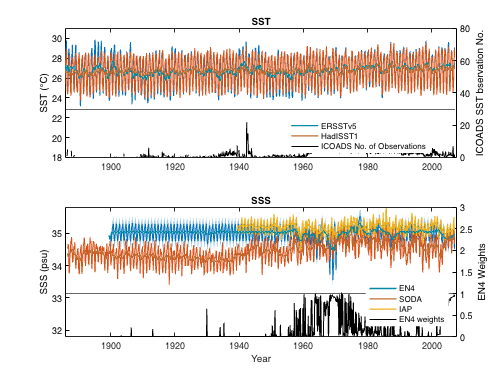

close
clf
subplot(2,1,1)

hold on
plot(SST.Date,SST.ERSSTv5,'LineWidth',0.4)
plot(SST.Date,SST.HadISST,'LineWidth',0.4)
plot(SST.Date,movmean(SST.ERSSTv5,13,'omitnan'),'color',[0 0.5470 0.6410],'LineWidth',1.5)
plot(SST.Date,movmean(SST.HadISST,13,'omitnan'),'color',[0.7500 0.4250 0.1980],'LineWidth',1.5)
ylabel('SST (°C)')
box on 
set(gca,'ylim',[18 31])


yyaxis right
time=[1800:1/12:2024-1/12]';
observatonNo=ncread('ICOADS_SST_No_48_56E_8_16N.nc','sst');
index2 = observatonNo==0;
observatonNo(index2)=nan;
hold on 
plot(time,observatonNo,'-k','LineWidth',0.5)
yline(30)
set(gca,'ylim',[0 80])
set(gca,'xlim',[1886 2007.59])
ylabel('ICOADS SST bservation No.')
legend({'Months with no observation','Months with at least 1 observation','Months with more than 5 observations'})
set(legend,'Box','off')
box on
ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';
lg = legend('','','ERSSTv5','HadISST1','ICOADS No. of Observations','Location','best');
set(lg,'box','off')
title('SST')

subplot(2,1,2)
hold on
patch(erroren4sssdate,EN4_err2,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.4)
plot(Time,EN4,'LineWidth',0.4)
plot(Time,SODA,'LineWidth',0.4)
plot(Time,IAP,'LineWidth',0.4)
plot(Time,movmean(EN4,13,'omitnan'),'color',[0 0.5470 0.6410],'LineWidth',1.5)
plot(Time,movmean(SODA,13,'omitnan'),'color',[0.7500 0.4250 0.1980],'LineWidth',1.5)
plot(Time,movmean(IAP,13,'omitnan'),'color',[0.9290 0.6940 0.1250],'LineWidth',1.5)
ylabel('SSS (psu)')
box on 
set(gca,'ylim',[31.8 35.8])


yyaxis right
hold on
plot(Time,EN4_ws,'-k','LineWidth',0.5)
yline(1)
set(gca,'ylim',[0 3])
set(gca,'xlim',[1886 2007.59])
ylabel('EN4 Weights')
ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';
lg = legend('','','','','EN4','SODA','IAP','EN4 weights','','Location','best');
set(lg,'box','off')
xlabel('Year')
title('SSS')

%%Sr/Ca monthly interpolation for 1671.583 - 2007.583
T = readtable('srca.xlsx','Sheet','endpoint');
T.SrCa(T.SrCa == 0) = nan;
T.RSD(T.RSD == 0) = nan;
Year = flip(fillmissing(T.Winters,"linear","SamplePoints",T.Depth)); %fill gap and flip
SrCa = flip(T.SrCa); %flip first to match age model 
SrCaerror = flip(T.RSD).*SrCa/100;
[SrCa,~] = fillmissing(SrCa,"linear","SamplePoints",Year); %fill gap 
[SrCaerror,~] = fillmissing(SrCaerror,"linear","SamplePoints",Year);
yearsst = [(1671+1/12*7):1/12:(2007+1/12*7)]'; %1671.583 - 2007.583
srcamonthly = interp1(Year,SrCa,yearsst,'linear',"extrap");
srcaerrorindividual = interp1(Year,SrCaerror,yearsst,'linear',"extrap");
srcaerrlongterm = 0.006;
srcaerrormonthly = sqrt(srcaerrorindividual.^2+srcaerrlongterm^2);

%%Annual Linear Extension 1672 = 1671 August to 1672 July
depth = T.Depth;
N = T.Winters;
[index,yr] = find(~isnan(N));
AER=diff(depth(index)); %annual extension rate
AER = flip(AER);

%% d18O monthly interpolation
T2 = readtable('d18O.xlsx','Sheet','endpoint');
T2.d18O(T2.d18O == 0) = nan;
year2 = flip(fillmissing(T2.Winters,"linear","SamplePoints",T2.Depth));
d18O = flip(T2.d18O);
[d18O,~] = fillmissing(d18O,"linear","SamplePoints",year2);
d18Omonthly = interp1(year2,d18O,yearsst,'linear',"extrap");
d18Oerrormonthly = ones(size(d18Omonthly))*0.1;



yr = (1672:2007)'; %annual mean Sr/Ca and d18O 1672 = 1671 August to 1672 July
gap = (1:12:4033)';
ASrCa=zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=srcamonthly(gap(i):(gap(i+1)-1));
    ASrCa(i) = mean(t,'omitnan');
i=i+1;
end

Ad18O=zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=d18Omonthly(gap(i):(gap(i+1)-1));
    Ad18O(i) = mean(t,'omitnan');
i=i+1;
end

Traw = array2table([srcamonthly,d18Omonthly],'VariableNames',{'SrCa','d18O'});
Traw.Mon = SST.Mon;
Traw.Date = SST.Date;
Traw.Mon = categorical(Traw.Mon);
Tsummer = vertcat(Traw((Traw.Mon=='1'),:),Traw((Traw.Mon=='2'),:),Traw((Traw.Mon=='3'),:),Traw((Traw.Mon=='12'),:));
Tsummer = sortrows(Tsummer,4);

Twinter = vertcat(Traw((Traw.Mon=='6'),:),Traw((Traw.Mon=='7'),:),Traw((Traw.Mon=='8'),:),Traw((Traw.Mon=='9'),:));
Twinter = sortrows(Twinter,4);
Twinter = Twinter(3:1342,:);

yr_s = (1672:2007)';
gap = (1:4:1345)';


summerSrCa = zeros(336,1);
for i=1:size(yr_s,1);
    t=Tsummer.SrCa(gap(i):(gap(i+1)-1));
    summerSrCa(i) = mean(t,'omitnan');
i=i+1;
end

summerd18O = zeros(336,1);
for i=1:size(yr_s,1);
    t=Tsummer.d18O(gap(i):(gap(i+1)-1));
    summerd18O(i) = mean(t,'omitnan');
i=i+1;
end

gap = (1:4:1341)';
yr_w = (1672:2006)';


winterSrCa= zeros(335,1);
for i=1:size(yr_w,1);
    t=Twinter.SrCa(gap(i):(gap(i+1)-1));
    winterSrCa(i) = mean(t,'omitnan');
i=i+1;
end


winterd18O= zeros(335,1);
for i=1:size(yr_w,1);
    t=Twinter.d18O(gap(i):(gap(i+1)-1));
    winterd18O(i) = mean(t,'omitnan');
i=i+1;
end

% test AER and Sr/Ca relationship
[r,p] = corr(detrend(ASrCa(216:end)),detrend(AER(216:end)))

r = -0.2787

p = 0.0020

[rs,ps] = corr(detrend(summerSrCa(216:end)),detrend(AER(216:end)))

rs = -0.3921

ps = 8.6542e-06

[rw,pw] = corr(detrend(winterSrCa(216:end)),detrend(AER(216:end-1)))

rw = -0.1839

pw = 0.0443


[r,p] = corr(detrend(Ad18O(216:end)),detrend(AER(216:end)))

r = 0.1132

p = 0.2163

[r,p] = corr(detrend(summerd18O(216:end)),detrend(AER(216:end)))

r = -0.0354

p = 0.6999

[r,p] = corr(detrend(winterd18O(216:end)),detrend(AER(216:end-1)))

r = -0.0122

p = 0.8947

[r,p] = corr(detrend(ASrCa(1:65)),detrend(AER(1:65)))

r = -0.2405

p = 0.0537

[rs,ps] = corr(detrend(summerSrCa(1:65)),detrend(AER(1:65)))

rs = -0.2232

ps = 0.0738

[rw,pw] = corr(detrend(winterSrCa(1:65)),detrend(AER(1:65)))

rw = -0.2487

pw = 0.0457


[r,p] = corr(detrend(Ad18O(1:65)),detrend(AER(1:65)))

r = -0.1206

p = 0.3385

[r,p] = corr(detrend(summerd18O(1:65)),detrend(AER(1:65)))

r = -0.1791

p = 0.1534

[r,p] = corr(detrend(winterd18O(1:65)),detrend(AER(1:65)))

r = -0.1516

p = 0.2280

r = -0.2405

p = 0.0537

rs = -0.2506

ps = 0.0441

rw = -0.2749

pw = 0.0267

r = -0.1206

p = 0.3385

r = -0.1823

p = 0.1461

r = -0.1282

p = 0.3088


k=1; %monthly sampling frequency 1 samples a year 
%cutoff frequency K month = 1/K samples/yr 
[m1,n1]=butter(5,(1/5)/(0.5*k),'low');
ASrCa_LPF = filtfilt(m1,n1,ASrCa);
AER_LPF = filtfilt(m1,n1,AER);
[r p] = corr(ASrCa_LPF(216:end), AER_LPF(216:end))

r = -0.5810

p = 2.8131e-12

n =length(ASrCa_LPF(216:end));
r1 = autocorr(ASrCa_LPF(216:end),1);
r1= r1(2);
r2=autocorr(ASrCa_LPF(216:end),1);
r2 = r2(2);
nadj = n.*(1-r1.*r2)./(1+r1.*r2)

nadj = 7.3480

t_stat = r * sqrt((nadj - 2) / (1 - r^2))

t_stat = -1.6509

p = 2 * (1 - tcdf(abs(t_stat), nadj - 2)) 

p = 0.1558

% test AER and d18O relationship

Ad18O_LPF = filtfilt(m1,n1,Ad18O);
[r p] = corr(Ad18O_LPF(216:end), AER_LPF(216:end))

r = -0.0133

p = 0.8847

n =length(Ad18O_LPF(216:end));
r1 = autocorr(Ad18O_LPF(216:end),1);
r1= r1(2);
r2=autocorr(Ad18O_LPF(216:end),1);
r2 = r2(2);
nadj = n.*(1-r1.*r2)./(1+r1.*r2)

nadj = 23.4757

t_stat = r * sqrt((nadj - 2) / (1 - r^2))

t_stat = -0.0617

p = 2 * (1 - tcdf(abs(t_stat), nadj - 2)) 

p = 0.9514

mean(AER(216:end))

ans = 13.9091

std(AER(216:end))*1.96

ans = 4.0722

lowgrowth = find(AER<mean(AER(216:end))-std(AER(216:end))*1.96);
yr(lowgrowth);
mean(AER(1:65))

ans = 11.1077

std(AER(1:65))*1.96

ans = 4.6501

# Figure 5.2

close
clf 
h = figure();
subplot(3,1,1)
hold on
plot(yearsst,srcamonthly,'color',[0.84 0.54 0.44])
plot(yr,ASrCa,'color',[0.84 0.34 0.24],'LineWidth',1)
[p, s]=polyfit(yr(216:end),ASrCa(216:end),1);
[p_ASrCa, delta]=polyconf(p,yr(216:end),s,"alpha",0.05);
 plot(yr(216:end),p_ASrCa,'r-', ...
      yr(216:end),p_ASrCa+delta, 'k--', ...
      yr(216:end),p_ASrCa-delta,'k--')
set(gca,'xlim',[1671 2050])
set(gca,'ydir','reverse')
ylabel('Sr/Ca ratio (mmol/mol)')
lg = legend('Monthly Sr/Ca-centred','Annual Sr/Ca-centred','Linear Trend','95% Confidence Interval','','location','best');
set(lg,'box','off')
box on 
h = breakxaxis([1738 1885]);

annotationAxes =   Axes with properties:

             XLim: [1671 2050]
             YLim: [8.7413 9.2338]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.7093 0.7750 0.2157]
            Units: 'normalized'

  Show all properties




subplot(3,1,2)
hold on
plot(yearsst,d18Omonthly)
plot(yr,Ad18O,'color',[0 0.4470 0.7410],'LineWidth',1)
[p, s]=polyfit(yr(216:end),Ad18O(216:end),1);
[p_Ad18O, delta]=polyconf(p,yr(216:end),s,"alpha",0.05);
 plot(yr(216:end),p_Ad18O,'b-', ...
      yr(216:end),p_Ad18O+delta, 'k--', ...
      yr(216:end),p_Ad18O-delta,'k--')
set(gca,'xlim',[1671 2050])
set(gca,'ydir','reverse')
ylabel('\delta^{18}O (‰VPDB)')
lg = legend('Monthly \delta^{18}O-centred','Annual \delta^{18}O-centred','Linear Trend','95% Confidence Interval','location','best');
set(lg,'box','off')
box on 
h = breakxaxis([1738 1885]);

annotationAxes =   Axes with properties:

             XLim: [1671 2050]
             YLim: [-5.2186 -3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.7750 0.2157]
            Units: 'normalized'

  Show all properties



subplot(3,1,3)
hold on
plot(yr,AER,'-k','LineWidth',1,'color',[0.4 0.4 0.4])
set(gca,'xlim',[1671 2050])

[p, s]=polyfit(yr(216:end),AER(216:end),1);
[p_AER, delta]=polyconf(p,yr(216:end),s,"alpha",0.05);
 plot(yr(216:end),p_AER,'k-', ...
      yr(216:end),p_AER+delta, 'k--', ...
      yr(216:end),p_AER-delta,'k--')

ylabel('Linear extension rate (mm)')
lg = legend('Annual linear extension rate','Linear Trend','95% Confidence Interval','location','best');
set(lg,'box','off')
box on 
h = breakxaxis([1738 1885]);

annotationAxes =   Axes with properties:

             XLim: [1671 2050]
             YLim: [5 25]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


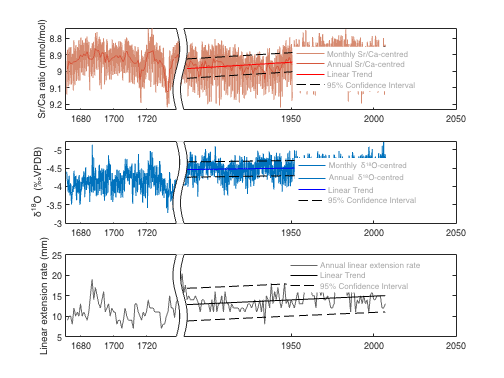

xlabel('Year')

SrCa_centred = srcamonthly - mean(srcamonthly);
d18O_centred = d18Omonthly - mean(d18Omonthly);

k1 = find(OISSTv2>0);
k1 = k1(1);
%SrCa
tic


tol = 1e-8;    % Tolerance
X = OISSTv2(k1:end)-mean(OISSTv2(k1:end));
sigX = OISSTv2error(k1:end);
Y = SrCa_centred(k1:end);
sigY = srcaerrormonthly(k1:end);


%% 3. Simple Linear Regression
% Performs simple linear regression (SLR) for comparison.

R = corrcoef(X,Y);
n = length(X);

ri = 0;
X1 = [n,sum(X);sum(X),sum(X.*X)];               % LSE Value of 'b'
Y1 = [sum(Y);sum(X.*Y)];                        % Polyfit can also be used
Z1 = X1\Y1;                                     % Matrix division
a1 = Z1(1);
b1 = Z1(2);

sigres = sum((Y - a1 - b1.*X).^2)/(n-2);        % Sigma Residual  s^2
delta = det(X1);  % Determinant              = n*(n-1)*varx 
varx = var(X);
sigb1sq = (n^2)*(n-1)*varx*sigres/(delta^2);    % Sigma(b) without weights
sigb1 = sqrt(sigb1sq); % standard error of slope 
Xbar = mean(X);

%siga1sq = (sigres/(varx*n))*(varx + Xbar^2) 
siga1sq = sigres*(1/n + Xbar^2/varx/(n-1)); 
siga1 = sqrt(siga1sq); % standard error of intercept
A_SLR = [a1 siga1];                             % SLR Intercept
B_SLR = [b1 sigb1];                            % SLR Slope

%---- SLR p-value ----

B1 = 0;
t1=(b1-B1)/sigb1;    % t = (m - m0)/SE
Pval1=2*(1-tcdf(abs(t1),n-2)); %?

%% 4. Maximum Likelihood Method (Weighted Linear Regression)
% Implements the _York et al._ [200.00104] algorithm to perform weighted linear
% regression using the maximum likelihood method (MLM).

%---- Weighting Errors ----

wX = abs(1./(sigX.^2));                     %weights w = 1/sig^2
wY = abs(1./(sigY.^2));
alpha = sqrt(wX.*wY);
%ri = mat(:,5);         % CorrCoef between sig(X) and sig(Y)

b = b1;                             
d = tol;                            
i = 0; 

%---- York et al. (2004) Algorithm ----

while (d > tol || d == tol)         % Tolerance check loop
    i = i+1;
    b2 = b;
    W = wX.*wY./((wX) + ((b^2).*wY) - (2.*b.*alpha.*ri));
    meanX = sum(W.*X)/sum(W);       %weighted mean
    meanY =  sum(W.*Y)/sum(W);      
    U = X(:) - meanX;
    V = Y(:) - meanY;
    Beta = W.*((U./wY)+((b.*V)./wX) - (b.*U + V).*(ri./alpha));
    meanBeta = sum(W.*Beta)/sum(W);
    b = sum(W.*Beta.*V)/sum(W.*Beta.*U);
    dif = b - b2;
    d = abs(dif);
end

U2 = U.^2;
V2 = V.^2;
a = meanY - b.*meanX;
x = meanX + Beta;
meanx = sum(W.*x)/sum(W);
u = x - meanx;
sigbsq = 1./(sum(W.*(u.*u)));
sigb = sqrt(sigbsq);
sigasq = 1./(sum(W)) + meanx^2.*(sigbsq);
siga = sqrt(sigasq);
S = sum(W.*((Y - b.*X - a)).^2);

%---- MLE p-value ----
B = 0;
t=(b-B)/sigb;
Pval=2*(1-tcdf(abs(t),length(X)-2));

%%RMA method
[rb,bintr,bintjm] = gmregress(X,Y,0.05);
B_RMA =  [rb(2),(bintr(2,2)-bintr(2,1))/3.92];
A_RMA = [rb(1), (bintr(1,2)-bintr(1,1))/3.92];

SSR = sum((Y - (rb(2).*X + rb(1))).^2);
SST = sum((Y - mean(Y)).^2);
rb_r = -1*sqrt(1 - SSR/SST);
rb_r2 = 1 - SSR/SST;


 A = [a siga];
 B = [b sigb];
 disp('--------------------------------------');

--------------------------------------


display('Weighted Linear Regression:');disp(' ');

Weighted Linear Regression:
 


wr = sum(U.*V)./sqrt((sum(U2).*sum(V2)));
display('Y = a + bX');display(' ');

Y = a + bX
 


disp('       a      siga');disp(A);

       a      siga
   -0.0297    0.0008



disp('       b      sigb');disp(B);

       b      sigb
   -0.0607    0.0006



disp(['r: ',num2str(wr)]);

r: -0.84783


disp(['r^2: ',num2str(wr^2)]);

r^2: 0.71882


disp(['p-value: ',num2str(Pval)]);

p-value: 0



disp('--------------------------------------');

--------------------------------------


display('Simple Linear Regression:');disp(' ');

Simple Linear Regression:
 


display('Y = a + bX');display(' ');

Y = a + bX
 


disp('       a      siga');disp(A_SLR);

       a      siga
   -0.0277    0.0027



disp('       b      sigb');disp(B_SLR);

       b      sigb
   -0.0494    0.0018



disp(['r: ',num2str(R(1,2))]);

r: -0.84683


disp(['r^2: ',num2str(R(1,2)^2)]);

r^2: 0.71713


disp(['p-value: ',num2str(Pval1)]);

p-value: 0


disp('--------------------------------------');

--------------------------------------


disp(['Total no. of iterations: ',num2str(i)]);

Total no. of iterations: 7


toc

Elapsed time is 0.250814 seconds.



disp('--------------------------------------');

--------------------------------------


display('Reduced Major Axis Regression:');disp(' ');

Reduced Major Axis Regression:
 


display('Y = a + bX');display(' ');

Y = a + bX
 


disp('       a      siga');disp(A_RMA);

       a      siga
   -0.0277         0



disp('       b      sigb');disp(B_RMA);

       b      sigb
   -0.0583    0.0018



disp(['r: ',num2str(rb_r)]);

r: -0.83287


disp(['r^2: ',num2str(rb_r2)]);

r^2: 0.69367


disp(['p-value: p<0.05']);

p-value: p<0.05


disp('--------------------------------------');

--------------------------------------


disp(['Total no. of iterations: ',num2str(i)]);

Total no. of iterations: 7


toc

Elapsed time is 0.294735 seconds.


# Figure 5.3a

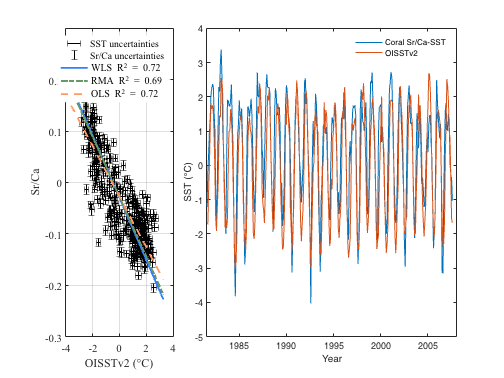

close
clf
subplot(1,3,1)
hold on;
set(gca,'FontSize',12,'FontName','Myriad Pro');
h0 = errorbar(X,Y,sigX,'horizontal','Marker','none','LineStyle','none','linewidth',0.3,'Color',[0 0 0]/256);
h1 = errorbar(X,Y,sigY,'Marker','none','LineStyle','none','linewidth',0.3,'Color',[0 0 0]/256); 
%c = uisetcolor([1 1 1])
grid on;   
plot(X,Y,'.k',MarkerSize=7)
p = min(X)-(max(X)-min(X))/10:(max(X)-min(X))/10:max(X)+(max(X)-min(X))/10;
q1 = a + (b.*p);
h2 = plot(p,q1,'linewidth',2,'Color',[0.2 0.5 1]);

q2 = rb(1)+(rb(2).*p);
h3 = plot(p,q2,'-.','LineWidth',2,'Color',[0.4 0.6 0.4]);

q3 = a1 + (b1.*p);
h4 = plot(p,q3,'--','LineWidth',2,'Color',[1 0.6 0.4]);
pl = legend([h0,h1,h2,h3,h4],'SST uncertainties','Sr/Ca uncertainties','WLS R^{2} = 0.72','RMA R^{2} = 0.69','OLS R^{2} = 0.72');
htext=findobj(get(pl,'children'),'type','text');
set(pl,'Box','off')
xlabel('OISSTv2 (°C)');
ylabel('Sr/Ca');
box on
xlim([-4 4])
ylim([-0.3 0.3])

subplot(1,3,[2,3])
hold on

plot(yearsst,SrCa_centred/b,'linewidth',1)
plot(yearsst,OISSTv2-mean(OISSTv2,'omitnan'),'linewidth',1)
set(gca,'xlim',[1981.58 2008])
box on 
xlabel('Year')
ylabel('SST (°C)')
lg=legend('Coral Sr/Ca-SST','OISSTv2');
set(lg,'box','off')

%d18O
tic


tol = 1e-8;    % Tolerance
X = OISSTv2(k1:end)-mean(OISSTv2(k1:end));
sigX = OISSTv2error(k1:end);
Y = d18O_centred(k1:end);
%Y = d18Omonthly(k1:end)-mean(d18Omonthly(k1:end));
sigY = d18Oerrormonthly(k1:end);


%% 3. Simple Linear Regression
% Performs simple linear regression (SLR) for comparison.

R = corrcoef(X,Y);
n = length(X);

ri = 0;
X1 = [n,sum(X);sum(X),sum(X.*X)];               % LSE Value of 'b'
Y1 = [sum(Y);sum(X.*Y)];                        % Polyfit can also be used
Z1 = X1\Y1;                                     % Matrix division
a1 = Z1(1);
b1 = Z1(2);

sigres = sum((Y - a1 - b1.*X).^2)/(n-2);        % Sigma Residual  s^2
delta = det(X1);  % Determinant              = n*(n-1)*varx 
varx = var(X);
sigb1sq = (n^2)*(n-1)*varx*sigres/(delta^2);    % Sigma(b) without weights
sigb1 = sqrt(sigb1sq); % standard error of slope 
Xbar = mean(X);

%siga1sq = (sigres/(varx*n))*(varx + Xbar^2) 
siga1sq = sigres*(1/n + Xbar^2/varx/(n-1)); 
siga1 = sqrt(siga1sq); % standard error of intercept
A_SLR = [a1 siga1];                             % SLR Intercept
B_SLR = [b1 sigb1];                            % SLR Slope

%---- SLR p-value ----

B1 = 0;
t1=(b1-B1)/sigb1;    % t = (m - m0)/SE
Pval1=2*(1-tcdf(abs(t1),n-2)); %?

%% 4. Maximum Likelihood Method (Weighted Linear Regression)
% Implements the _York et al._ [200.00104] algorithm to perform weighted linear
% regression using the maximum likelihood method (MLM).

%---- Weighting Errors ----

wX = abs(1./(sigX.^2));                     %weights w = 1/sig^2
wY = abs(1./(sigY.^2));
alpha = sqrt(wX.*wY);
%ri = mat(:,5);         % CorrCoef between sig(X) and sig(Y)

b = b1;                             
d = tol;                            
i = 0; 

%---- York et al. (2004) Algorithm ----

while (d > tol || d == tol)         % Tolerance check loop
    i = i+1;
    b2 = b;
    W = wX.*wY./((wX) + ((b^2).*wY) - (2.*b.*alpha.*ri));
    meanX = sum(W.*X)/sum(W);       %weighted mean
    meanY =  sum(W.*Y)/sum(W);      
    U = X(:) - meanX;
    V = Y(:) - meanY;
    Beta = W.*((U./wY)+((b.*V)./wX) - (b.*U + V).*(ri./alpha));
    meanBeta = sum(W.*Beta)/sum(W);
    b = sum(W.*Beta.*V)/sum(W.*Beta.*U);
    dif = b - b2;
    d = abs(dif);
end

U2 = U.^2;
V2 = V.^2;
a = meanY - b.*meanX;
x = meanX + Beta;
meanx = sum(W.*x)/sum(W);
u = x - meanx;
sigbsq = 1./(sum(W.*(u.*u)));
sigb = sqrt(sigbsq);
sigasq = 1./(sum(W)) + meanx^2.*(sigbsq);
siga = sqrt(sigasq);
S = sum(W.*((Y - b.*X - a)).^2);

%---- MLE p-value ----
B = 0;
t=(b-B)/sigb;
Pval=2*(1-tcdf(abs(t),length(X)-2));


%%RMA method
[rb,bintr,bintjm] = gmregress(X,Y,0.05);
B_RMA =  [rb(2),(bintr(2,2)-bintr(2,1))/3.92];
A_RMA = [rb(1), (bintr(1,2)-bintr(1,1))/3.92];

SSR = sum((Y - (rb(2).*X + rb(1))).^2);
SST = sum((Y - mean(Y)).^2);
rb_r = -1*sqrt(1 - SSR/SST);
rb_r2 = 1 - SSR/SST;


 A = [a siga];
 B = [b sigb];
 disp('--------------------------------------');
display('Weighted Linear Regression:');disp(' ');
wr = sum(U.*V)./sqrt((sum(U2).*sum(V2)));
display('Y = a + bX');display(' ');
disp('       a      siga');disp(A);
disp('       b      sigb');disp(B);
disp(['r: ',num2str(wr)]);
disp(['r^2: ',num2str(wr^2)]);
disp(['p-value: ',num2str(Pval)]);

disp('--------------------------------------');
display('Simple Linear Regression:');disp(' ');
display('Y = a + bX');display(' ');
disp('       a      siga');disp(A_SLR);
disp('       b      sigb');disp(B_SLR);
disp(['r: ',num2str(R(1,2))]);
disp(['r^2: ',num2str(R(1,2)^2)]);
disp(['p-value: ',num2str(Pval1)]);
disp('--------------------------------------');
disp(['Total no. of iterations: ',num2str(i)]);
toc


disp('--------------------------------------');
display('Reduced Major Axis Regression:');disp(' ');
display('Y = a + bX');display(' ');
disp('       a      siga');disp(A_RMA);
disp('       b      sigb');disp(B_RMA);
disp(['r: ',num2str(rb_r)]);
disp(['r^2: ',num2str(rb_r2)]);
disp(['p-value: p<0.05']);
disp('--------------------------------------');
disp(['Total no. of iterations: ',num2str(i)]);
toc

# Figure 5.3b

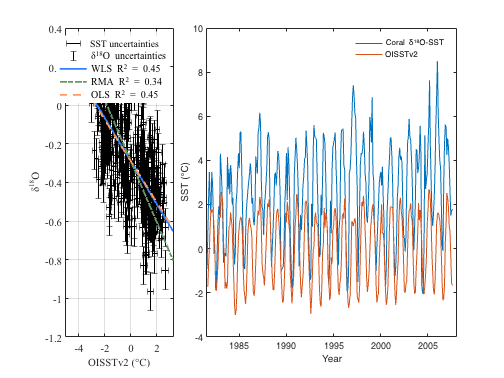

close
clf
subplot(1,3,1)
hold on;
set(gca,'FontSize',12,'FontName','Myriad Pro');
h0 = errorbar(X,Y,sigX,'horizontal','Marker','none','LineStyle','none','linewidth',0.3,'Color',[0 0 0]/256);
h1 = errorbar(X,Y,sigY,'Marker','none','LineStyle','none','linewidth',0.3,'Color',[0 0 0]/256); 
%c = uisetcolor([1 1 1])
grid on;   
plot(X,Y,'.k',MarkerSize=7)
p = min(X)-(max(X)-min(X))/10:(max(X)-min(X))/10:max(X)+(max(X)-min(X))/10;
q1 = a + (b.*p);
h2 = plot(p,q1,'linewidth',2,'Color',[0.2 0.5 1]);

q2 = rb(1)+(rb(2).*p);
h3 = plot(p,q2,'-.','LineWidth',2,'Color',[0.4 0.6 0.4]);

q3 = a1 + (b1.*p);
h4 = plot(p,q3,'--','LineWidth',2,'Color',[1 0.6 0.4]);
pl = legend([h0,h1,h2,h3,h4],'SST uncertainties','\delta^{18}O uncertainties','WLS R^{2} = 0.45','RMA R^{2} = 0.34','OLS R^{2} = 0.45');
htext=findobj(get(pl,'children'),'type','text');
set(pl,'Box','off')
set(htext,'FontName','Times New Roman','Fontsize',12);
xl = xlabel('OISSTv2 (°C)');
set(xl,'FontName','Times New Roman','FontSize',12);
yl = ylabel('\delta^{18}O');
set(yl,'FontName','Times New Roman','FontSize',12);

box on


subplot(1,3,[2,3])
hold on

plot(yearsst,d18O_centred/b,'linewidth',1)
plot(yearsst,OISSTv2-mean(OISSTv2,'omitnan'),'linewidth',1)
set(gca,'xlim',[1981.58 2008])
box on 
xlabel('Year')
ylabel('SST (°C)')
lg=legend('Coral \delta^{18}O-SST','OISSTv2');
set(lg,'box','off')

RC1= readtable('Running corr.xlsx','sheet','ERSSTd18O1886');

yrrc1 = RC1.year_;
corr1=RC1.x__Corr___;
p1=RC1.x_Prob___;
% 2.5%
l1 = RC1.x2_5cl;
% 97.50%
l2 = RC1.x97_5cl;

RC2= readtable('Running corr.xlsx','sheet','HadISSTd18O1886');

yrrc2 = RC2.year_;
corr2=RC2.x__Corr___;
p2=RC2.x_Prob___;
% 2.5%
l3 = RC2.x2_5cl;
% 97.50%
l4 = RC2.x97_5cl;

RC3= readtable('Running corr.xlsx','sheet','ERSSTSrCa1886');

yrrc3 = RC3.year_;
corr3=RC3.x__Corr___;
p3=RC3.x_Prob___;
% 2.5%
l5 = RC3.x2_5cl;
% 97.50%
l6 = RC3.x97_5cl;

RC4= readtable('Running corr.xlsx','sheet','HadISSTSrCa1886');

yrrc4 = RC4.year_;
corr4=RC4.x__Corr___;
p4=RC4.x_Prob___;
% 2.5%
l7 = RC4.x2_5cl;
% 97.50%
l8 = RC4.x97_5cl;

# Figure 5.4

close
clf('reset')
subplot (2,1,1)
hold on
plot(yrrc3,corr3,'LineWidth',1.5,'color',[0.8 0.5 0])
plot(yrrc4,corr4,'LineWidth',1.5,'color',[0.6 0.2 0])
plot(yrrc3,l5,'--','LineWidth',1.5,'color',[0.8 0.5 0])
plot(yrrc3,l6,'--','LineWidth',1.5,'color',[0.8 0.5 0])
plot(yrrc4,l7,'--','LineWidth',1.5,'color',[0.6 0.2 0])
plot(yrrc4,l8,'--','LineWidth',1.5,'color',[0.6 0.2 0])
yline(0,'-k')

patch([1960 1990 1990 1960],[1 1 -1 -1],[200 30 30]/256,'Edgecolor','none','Facealpha',0.1)
leg = legend('ERSSTv5-Sr/Ca','HadISST1-Sr/Ca')

leg =   Legend (ERSSTv5-Sr/Ca, HadISST1-Sr/Ca) with properties:

         String: {'ERSSTv5-Sr/Ca'  'HadISST1-Sr/Ca'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6973 0.8488 0.1937 0.0631]
          Units: 'normalized'

  Show all properties


set(leg,'Box','off','location','best')
ylabel('correlation')
hold off
box on


subplot (2,1,2)
hold on
plot(yrrc1,corr1,'LineWidth',1.5,'color',[0 0.5 0.8])
plot(yrrc2,corr2,'LineWidth',1.5,'color',[0 0.2 0.6])

plot(yrrc1,l1,'--','LineWidth',1.5,'color',[0 0.5 0.8])
plot(yrrc1,l2,'--','LineWidth',1.5,'color',[0 0.5 0.8])
plot(yrrc2,l3,'--','LineWidth',1.5,'color',[0 0.2 0.6])
plot(yrrc2,l4,'--','LineWidth',1.5,'color',[0 0.2 0.6])

yline(0,'-k')
leg = legend('ERSSTv5-\delta^{18}O','HadISST1-\delta^{18}O')

leg =   Legend (ERSSTv5-\delta^{18}O, HadISST1-\delta^{18}O) with properties:

         String: {'ERSSTv5-\delta^{18}O'  'HadISST1-\delta^{18}O'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7036 0.3631 0.1875 0.0750]
          Units: 'normalized'

  Show all properties


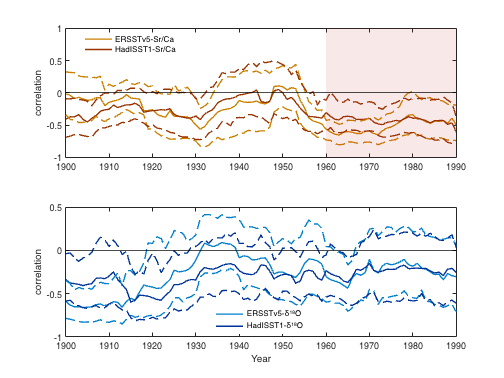

set(leg,'Box','off','location','best')
ylabel('correlation')
hold off
box on
xlabel('Year')

% breakxaxes splits data in an axes so that data is in a left and right pane.
%
%   breakXAxes(splitXLim) splitXLim is a 2 element vector containing a range
%   of x values from splitXLim(1) to splitXLim(2) to remove from the axes.
%   They must be within the current xLimis of the axes.
%
%   breakXAxes(splitXLim,splitWidth) splitWidth is the distance to 
%   seperate the left and right side.  Units are the same as 
%   get(AX,'uints') default is 0.015
% 
%   breakXAxes(splitXLim,splitWidth,yOverhang) yOverhang stretches the 
%   axis split graphic to extend past the top and bottom of the plot by
%   the distance set by YOverhang.  Units are the same as get(AX,'units')
%   default value is 0.015
%
%   breakXAxes(AX, ...) performs the operation on the axis specified by AX
%


% breakxaxes splits data in an axes so that data is in a left and right pane.
%
%   breakXAxes(splitXLim) splitXLim is a 2 element vector containing a range
%   of x values from splitXLim(1) to splitXLim(2) to remove from the axes.
%   They must be within the current xLimis of the axes.
%
%   breakXAxes(splitXLim,splitWidth) splitWidth is the distance to 
%   seperate the left and right side.  Units are the same as 
%   get(AX,'uints') default is 0.015
% 
%   breakXAxes(splitXLim,splitWidth,yOverhang) yOverhang stretches the 
%   axis split graphic to extend past the top and bottom of the plot by
%   the distance set by YOverhang.  Units are the same as get(AX,'units')
%   default value is 0.015
%
%   breakXAxes(AX, ...) performs the operation on the axis specified by AX
%

function breakInfo = breakxaxis(varargin)

    %Validate Arguements
    if nargin < 1 || nargin > 4
       error('Wrong number of arguements'); 
    end

    if isscalar(varargin{1}) && ishandle(varargin{1})
        mainAxes = varargin{1};
        argOffset = 1;
        argCnt = nargin - 1;
        if ~strcmp(get(mainAxes,'Type'),'axes')
           error('Handle object must be Type Axes'); 
        end
    else
        mainAxes = gca;
        argOffset = 0;
        argCnt = nargin;
    end
    
    if (strcmp(get(mainAxes,'XScale'),'log'))
        error('Log X Axes are not supported'); 
    end
    
    if (argCnt < 3)
        yOverhang = 0.015;
    else
        yOverhang = varargin{3 + argOffset};
        if  numel(yOverhang) ~= 1 || ~isreal(yOverhang) || ~isnumeric(yOverhang)
            error('YOverhang must be a scalar number');
        elseif (yOverhang < 0)
            error('YOverhang must not be negative');
        end
        yOverhang = double(yOverhang);
    end
    
    if (argCnt < 2)
        splitWidth = 0.015;
    else
        splitWidth = varargin{2 + argOffset};
        if  numel(yOverhang) ~= 1 || ~isreal(yOverhang) || ~isnumeric(yOverhang)
            error('splitWidth must be a scalar number');
        elseif (yOverhang < 0)
            error('splitWidth must not be negative');
        end
        splitWidth = double(splitWidth);
    end
    
    splitXLim = varargin{1 + argOffset};
    if numel(splitXLim) ~= 2 || ~isnumeric(splitXLim) || ~isreal(yOverhang)
       error(splitXLim,'Must be a vector length 2');
    end
    splitXLim = double(splitXLim);
    
    mainXLim = get(mainAxes,'XLim');
    if (any(splitXLim >= mainXLim(2)) || any(splitXLim <= mainXLim(1)))
       error('splitXLim must be in the range given by get(AX,''XLim'')');
    end
    
    mainPosition = get(mainAxes,'Position');
    if (splitWidth > mainPosition(3) ) 
       error('Split width is too large') 
    end
   
    %We need to create 4 axes
    % leftAxes - is used for the left x axis and left pane data
    % rightAxes - is used to the right x axis and right pane data
    % annotationAxes - is used to display the y axis and title
    % breakAxes - this is an axes with the same size and position as main
    %   is it used to draw a seperator between the left and right side
    

    %Grab Some Parameters from the main axis (e.g the one we are spliting)
    mainXLim = get(mainAxes,'XLim');
    mainYLim = get(mainAxes,'YLim');
    mainPosition = get(mainAxes,'Position');
    mainParent = get(mainAxes,'Parent');
    mainWidth = mainPosition(3); %Positions have the format [left bottom width height]
    %mainXRange = mainXLim(2) - mainXLim(1);
    mainFigure = get(mainAxes,'Parent');
    mainYColor = get(mainAxes,'YColor');
    mainLineWidth = get(mainAxes,'LineWidth');
    figureColor = get(mainFigure,'Color');
    mainYTickLabelMode = get(mainAxes,'YTickLabelMode');
    mainXLabel = get(mainAxes,'XLabel');
    mainXDir = get(mainAxes,'XDir');
    mainLayer = get(mainAxes,'Layer');
    
    %Save Main Axis Z Order
    figureChildren = get(mainFigure,'Children');
    zOrder = find(figureChildren == mainAxes);
    
    %Calculate where axesLeft and axesRight will be layed on screen
    %And their respctive XLimits
    leftXLimTemp = [mainXLim(1) splitXLim(1)];
    rightXLimTemp = [splitXLim(2) mainXLim(2)];

    leftXRangeTemp = leftXLimTemp(2) - leftXLimTemp(1);
    rightXRangeTemp = rightXLimTemp(2) - rightXLimTemp(1);

    leftWidthTemp = leftXRangeTemp / (leftXRangeTemp + rightXRangeTemp) * (mainWidth - splitWidth);
    rightWidthTemp = rightXRangeTemp / (leftXRangeTemp + rightXRangeTemp) * (mainWidth - splitWidth);

    leftStretch = (leftWidthTemp + splitWidth/2) / leftWidthTemp;
    leftXRange = leftXRangeTemp * leftStretch;
    leftWidth = leftWidthTemp * leftStretch;

    rightStretch = (rightWidthTemp + splitWidth/2) / rightWidthTemp;
    rightXRange = rightXRangeTemp * rightStretch;
    rightWidth = rightWidthTemp * rightStretch;
    
    leftXLim = [mainXLim(1) mainXLim(1)+leftXRange];
    rightXLim = [mainXLim(2)-rightXRange mainXLim(2)];
    
    if (strcmp(mainXDir, 'normal')) 
        leftPosition = mainPosition;
        leftPosition(3) = leftWidth; 

        rightPosition = mainPosition;
        rightPosition(1) = mainPosition(1) + leftWidth;
        rightPosition(3) = rightWidth;
    else
        %Left Axis will actually go on the right side a vise versa
        rightPosition = mainPosition;
        rightPosition(3) = rightWidth; 

        leftPosition = mainPosition;
        leftPosition(1) = mainPosition(1) + rightWidth;
        leftPosition(3) = leftWidth;
    end
 
    %Create the Annotations layer, if the Layer is top, draw the axes on
    %top (e.g. after) drawing the left and right pane
    if strcmp(mainLayer,'bottom')
        annotationAxes = CreateAnnotaionAxes(mainAxes,mainParent)
    end
    
    %Create and position the leftAxes. Remove all Y Axis Annotations, the 
    %title, and a potentially offensive tick mark 
    leftAxes = copyobj(mainAxes,mainParent);
    set(leftAxes,'Position', leftPosition, ...
        'XLim', leftXLim, ...
        'YLim', mainYLim, ...
        'YGrid' ,'off', ...
        'YMinorGrid', 'off', ...
        'YMinorTick','off', ...
        'YTick', [], ...
        'YTickLabel', [], ...
        'box','off');
    if strcmp(mainLayer,'bottom')
        set(leftAxes,'Color','none');
    end
    delete(get(leftAxes,'YLabel')); 
    delete(get(leftAxes,'XLabel'));
    delete(get(leftAxes,'Title'));
    
    if strcmp(mainYTickLabelMode,'auto')
        xTick =  get(leftAxes,'XTick');
        set(leftAxes,'XTick',xTick(1:(end-1)));
    end
    
    %Create and position the rightAxes. Remove all Y Axis annotations, the 
    %title, and a potentially offensive tick mark 
    rightAxes = copyobj(mainAxes,mainParent);
    set(rightAxes,'Position', rightPosition, ...
        'XLim', rightXLim, ...
        'YLim', mainYLim, ...
        'YGrid' ,'off', ...
        'YMinorGrid', 'off', ...
        'YMinorTick','off', ...
        'YTick', [], ...
        'YTickLabel', [], ...
        'box','off');
    if strcmp(mainLayer,'bottom')
        set(rightAxes,'Color','none');
    end
    delete(get(rightAxes,'YLabel')); 
    delete(get(rightAxes,'XLabel'));
    delete(get(rightAxes,'Title'));
    
    if strcmp(mainYTickLabelMode,'auto')
        xTick =  get(rightAxes,'XTick');
        set(rightAxes,'XTick',xTick(2:end));
    end

        %Create the Annotations layer, if the Layer is top, draw the axes on
    %top (e.g. after) drawing the left and right pane
    if strcmp(mainLayer,'top')
        annotationAxes = CreateAnnotaionAxes(mainAxes,mainParent);
        set(annotationAxes, 'Color','none');
    end
    
    %Create breakAxes, remove all graphics objects and hide all annotations
    breakAxes = copyobj(mainAxes,mainParent);
    children = get(breakAxes,'Children');
    for i = 1:numel(children)
       delete(children(i)); 
    end
    
    set(breakAxes,'Color','none');
    %Stretch the breakAxes vertically to cover the horzontal axes lines
    orignalUnits = get(breakAxes,'Units');
    set(breakAxes,'Units','Pixel');
    breakPosition = get(breakAxes,'Position');
    nudgeFactor = get(breakAxes,'LineWidth');
    breakPosition(4) = breakPosition(4) +  nudgeFactor;
    set(breakAxes,'Position',breakPosition);
    set(breakAxes,'Units',orignalUnits);

    %Stretch the breakAxes vertically to create an overhang for sylistic
    %effect
    breakPosition = get(breakAxes,'Position');
    breakPosition(2) = breakPosition(2) - yOverhang;
    breakPosition(4) = breakPosition(4) +  2*yOverhang;
    set(breakAxes,'Position',breakPosition);
    
    %Create a sine shaped patch to seperate the 2 sides
    breakXLim = [mainPosition(1) mainPosition(1)+mainPosition(3)];
    set(breakAxes,'xlim',breakXLim);
    theta = linspace(0,2*pi,100);
    yPoints = linspace(mainYLim(1),mainYLim(2),100);
    amp = splitWidth/2 * 0.9;
    xPoints1 = amp * sin(theta) + mainPosition(1) + leftWidthTemp;
    xPoints2 = amp * sin(theta) + mainPosition(1) + mainPosition(3) - rightWidthTemp;
    patchPointsX = [xPoints1 xPoints2(end:-1:1) xPoints1(1)];
    patchPointsY = [yPoints  yPoints(end:-1:1)  yPoints(1)];
    patch(patchPointsX,patchPointsY ,figureColor,'EdgeColor',figureColor,'Parent',breakAxes);

    %Create A Line To Delineate the left and right edge of the patch
    line('xData',xPoints1,'ydata',yPoints,'Parent',breakAxes,'Color',mainYColor,'LineWidth',mainLineWidth);
    line('xData',xPoints2,'ydata',yPoints,'Parent',breakAxes,'Color',mainYColor,'LineWidth',mainLineWidth);

    set(breakAxes,'Visible','off');
    
    %Make the old main axes invisiable
    invisibleObjects = RecursiveSetVisibleOff(mainAxes);

    %Preserve the z-order of the figure
    uistack([leftAxes rightAxes breakAxes annotationAxes],'down',zOrder)
    
    %Set the rezise mode to position so that we can dynamically change the
    %size of the figure without screwing things up
    set([leftAxes rightAxes breakAxes annotationAxes],'ActivePositionProperty','Position');
 
    %Playing with the titles labels etc can cause matlab to reposition
    %the axes in some cases.  Mannually force the position to be correct. 
    set([breakAxes annotationAxes],'Position',mainPosition);
    
    %Save the axes so we can unbreak the axis easily
    breakInfo = struct();
    breakInfo.leftAxes = leftAxes;
    breakInfo.rightAxes = rightAxes;
    breakInfo.breakAxes = breakAxes;
    breakInfo.annotationAxes = annotationAxes;
    breakInfo.invisibleObjects = invisibleObjects;
end

function list = RecursiveSetVisibleOff(handle) 
    list = [];
    list = SetVisibleOff(handle,list);
    
end 

function list = SetVisibleOff(handle, list)
    if (strcmp(get(handle,'Visible'),'on'))
        set(handle,'Visible','off');
        list = [list handle];
    end
    
    children = get(handle,'Children');
    for i = 1:numel(children)
        list = SetVisibleOff(children(i),list);
    end
end
    
function annotationAxes = CreateAnnotaionAxes(mainAxes,mainParent)

    %Create Annotation Axis, Remove graphics objects, XAxis annotations
    %(except XLabel) and make background transparent
    annotationAxes = copyobj(mainAxes,mainParent);
    
    set(annotationAxes,'YLimMode','Manual');
    
    children = get(annotationAxes,'Children');
    for i = 1:numel(children)
       delete(children(i)); 
    end

    %Save the xLabelpostion because it will move when we delete xAxis
    %ticks
    xLabel = get(annotationAxes,'XLabel');
    xLabelPosition = get(xLabel,'Position');
    
    set(annotationAxes,'XGrid' ,'off', ...
        'XMinorGrid', 'off', ...
        'XMinorTick','off', ...
        'XTick', [], ...
        'XTickLabel', []);
    
    %Restore the pevious label postition
    set(xLabel,'Position',xLabelPosition);
end




function [b,bintr,bintjm] = gmregress(x,y,alpha)
%GMREGRESS Geometric Mean Regression (Reduced Major Axis Regression).
%   Model II regression should be used when the two variables in the
%   regression equation are random and subject to error, i.e. not 
%   controlled by the researcher. Model I regression using ordinary least 
%   squares underestimates the slope of the linear relationship between the
%   variables when they both contain error. According to Sokal and Rohlf 
%   (1995), the subject of Model II regression is one on which research and
%   controversy are continuing and definitive recommendations are difficult
%   to make.
%
%   GMREGRESS is a Model II procedure. It standardize variables before the 
%   slope is computed. Each of the two variables is transformed to have a 
%   mean of zero and a standard deviation of one. The resulting slope is
%   the geometric mean of the linear regression coefficient of Y on X. 
%   Ricker (1973) coined this term and gives an extensive review of Model
%   II regression. It is also known as Standard Major Axis.
%
%   [B,BINTR,BINTJM] = GMREGRESS(X,Y,ALPHA) returns the vector B of 
%   regression coefficients in the linear Model II and a matrix BINT of the
%   given confidence intervals for B by the Ricker (1973) and Jolicoeur and
%   Mosimann (1968)-McArdle (1988) procedure.
%
%   GMREGRESS treats NaNs in X or Y as missing values, and removes them.
%
%   Syntax: function [b,bintr,bintjm] = gmregress(x,y,alpha)
%
%   Example. From the Box 14.12 (California fish cabezon [Scorpaenichthys 
%   marmoratus]) of Sokal and Rohlf (1995). The data are:
%
%   x=[14,17,24,25,27,33,34,37,40,41,42];
%   y=[61,37,65,69,54,93,87,89,100,90,97];
%
%   Calling on Matlab the function: 
%                [b,bintr,bintjm] = gmregress(x,y)
%
%   Answer is:
%
%   b =
%      12.1938    2.1194
%
%   bintr =
%     -10.6445   35.0320
%       1.3672    2.8715
%   
%   bintjm =
%     -14.5769   31.0996
%       1.4967    3.0010
%
%   Created by A. Trujillo-Ortiz and R. Hernandez-Walls
%             Facultad de Ciencias Marinas
%             Universidad Autonoma de Baja California
%             Apdo. Postal 453
%             Ensenada, Baja California
%             Mexico.
%             atrujo@uabc.edu.mx
%
%   Copyright (C)  June 15, 2010. 
%
%   To cite this file, this would be an appropriate format:
%   Trujillo-Ortiz, A. and R. Hernandez-Walls. (2010). gmregress: 
%      Geometric Mean Regression (Reduced Major Axis Regression).  
%      A MATLAB file. [WWW document]. URL http://www.mathworks.com/
%      matlabcentral/fileexchange/27918-gmregress
%    
%   References:
%   Jolicoeur, P. and Mosimann, J. E. (1968), Intervalles de confiance pour
%              la pente de l�axe majeur d�une distribution normale 
%              bidimensionnelle. Biométrie-Praximétrie, 9:121-140.
%   McArdle, B. (1988), The structural relationship:regression in biology.
%              Can. Jour. Zool. 66:2329-2339.
%   Ricker, W. E. (1973), Linear regression in fishery research. J. Fish.
%              Res. Board Can., 30:409-434. 
%   Sokal, R. R. and Rohlf, F. J. (1995), Biometry. The principles and
%              practice of the statistics in biologicalreserach. 3rd. ed.
%              New-York:W.H.,Freeman. [Sections 14.13 and 15.7] 
%

if  nargin < 2
    error('gmregress:TooFewInputs', ...
          'GMREGRESS requires at least two input arguments.');
elseif nargin == 2
    alpha = 0.05;
end

x = x(:); y = y(:);

% Check that matrix (X) and rigth hand side (Y) have compatible dimensions
[n,ncolx] = size(x);
if ~isvector(y)
    error('gmregress:InvalidData', 'Y must be a vector.');
elseif numel(y) ~= n
    error('gmregress:InvalidData', ...
          'The number of rows in Y must equal the number of rows in X.');
end

% Remove missing values, if any
wasnan = (isnan(y) | any(isnan(x),2));
havenans = any(wasnan);
if havenans
   y(wasnan) = [];
   x(wasnan,:) = [];
   n = length(y);
end

R = corrcoef(x,y);
r = R(1,2); %correlation coefficient
s = r/abs(r); %find sign of the correlation coefficient: this former bug 
              %was efficiently corrected thanks to the valuable suggestions
              %given by Holger Goerlitz and Joel E. Cohen. Yes, a negative
              %slope are always negative!
S = cov(x,y);
SCX = S(1,1)*(n-1);
SCY = S(2,2)*(n-1);
SCP = S(1,2)*(n-1);
v = s*sqrt(SCY/SCX); %slope
u = mean(y)-mean(x)*v; %intercept
b = [u v];

%Ricker procedure
SCv = SCY-(SCP^2)/SCX;
N = SCv/(n-2);
sv = sqrt(N/SCX);
t = tinv(1-(alpha/2),n-2);
vi = v-t*sv; %confidence lower limit of slope
vs = v+t*sv; %confidence upper limit of slope
ui = mean(y)-mean(x)*vs; %confidence lower limit of intercept
us = mean(y)-mean(x)*vi; %confidence upper limit of intercept
uint = [ui us];
vint = [vi vs];
if ui > us
    uint([2 1]) = uint([1 2]);
else
end

if vi > vs
    vint([2 1]) = vint([1 2]);
else
end
bintr = [uint;vint];

%Jolicoeur and Mosimann procedure
r = R(1,2);
F =finv(1-alpha,1,n-2);
B = F*(1-r^2)/(n-2);
a = sqrt(B+1);
c = sqrt(B);
qi = v*(a-c); %confidence lower limit of slope
qs = v*(a+c); %confidence upper limit of slope
pi = mean(y)-mean(x)*qs; %confidence lower limit of intercept
ps = mean(y)-mean(x)*qi; %confidence upper limit of intercept
pint = [pi ps];
qint = [qi qs];
if pi > ps
    pint([2 1]) = pint([1 2]);
else
end

if qi > qs
    qint([2 1]) = qint([1 2]);
else
end
bintjm = [pint;qint];

return,
end

